**Model Sensitivity**

Settling velocity depends on:

- Particle size

- Particle density

Particle density depends on:

- Amount of attached algae

Attached algae depends on:

- Time

- Algal Flux

Algal Flux depends on:

- Collisions

- Growth

- Mortality

- Respiration

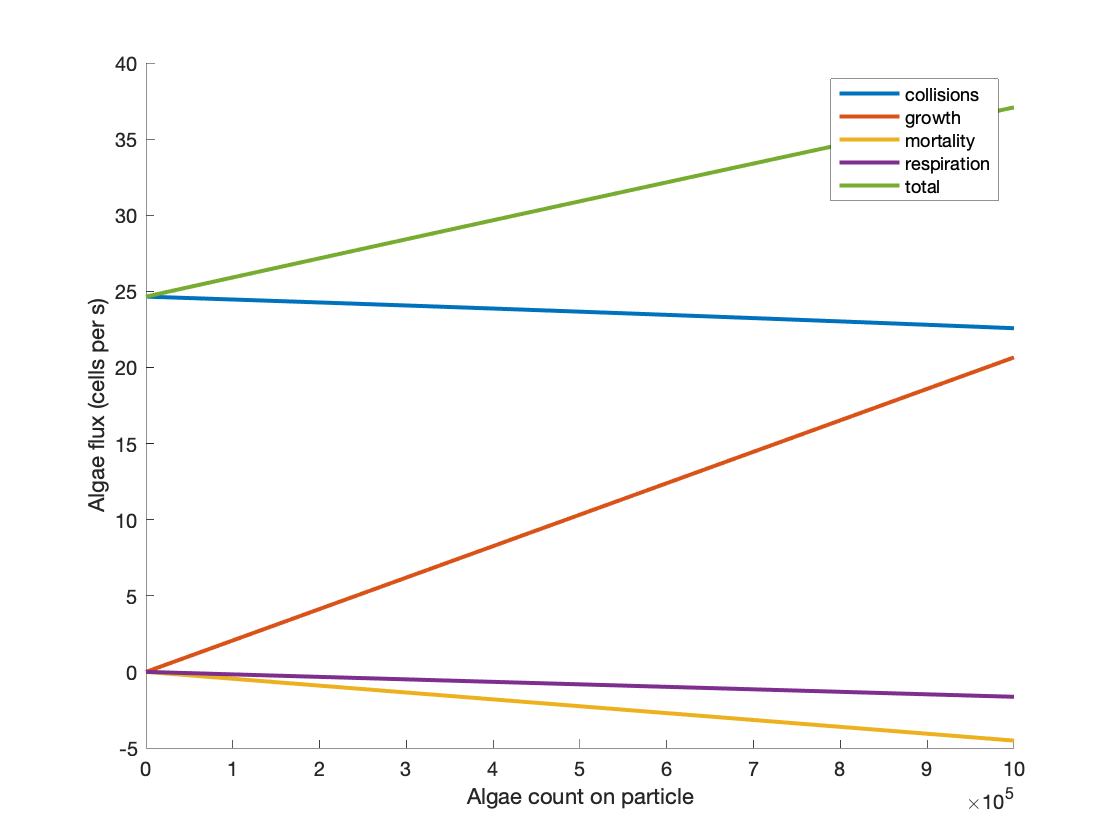

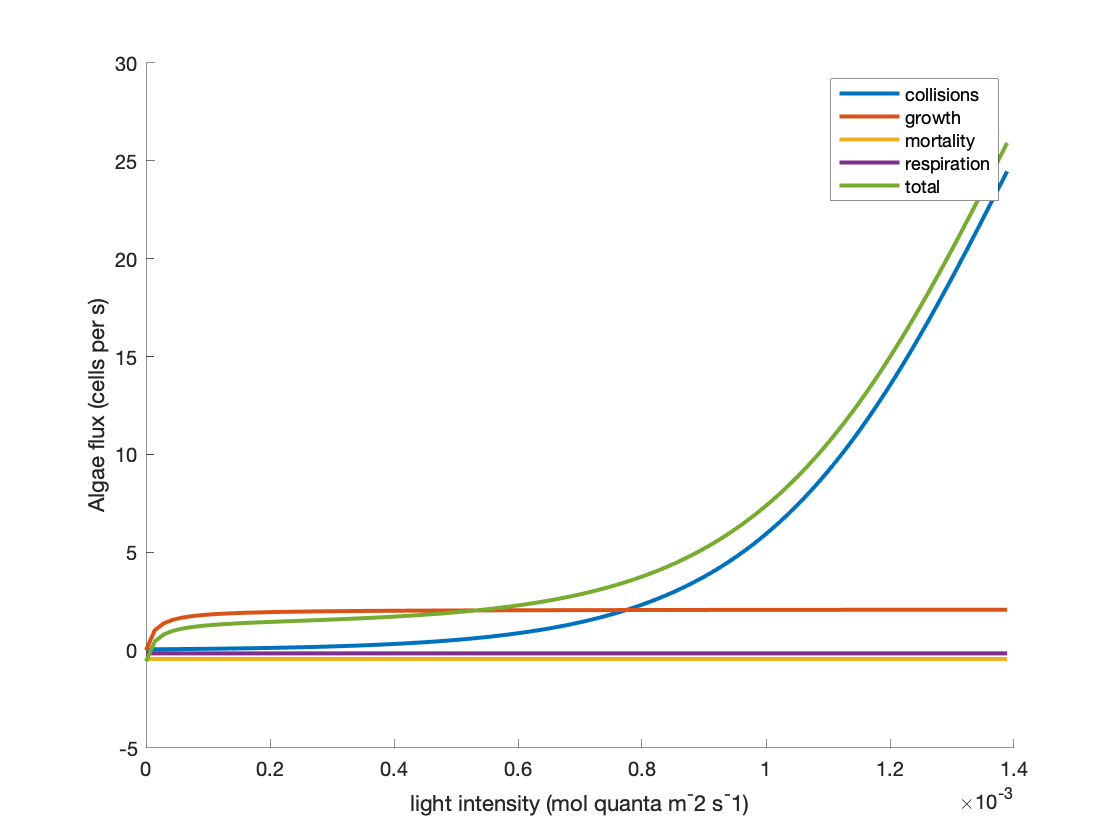

run("get_algae_flux_for_particle_test.m")

Collisions:

Only matters when there's little algae, but necessary to start things.  Only matters at the surface.

Depends on everything.

Impacts: time until particle begins settling.

Growth:

Depends on: temp, light

Temp varies little in the upper ocean.

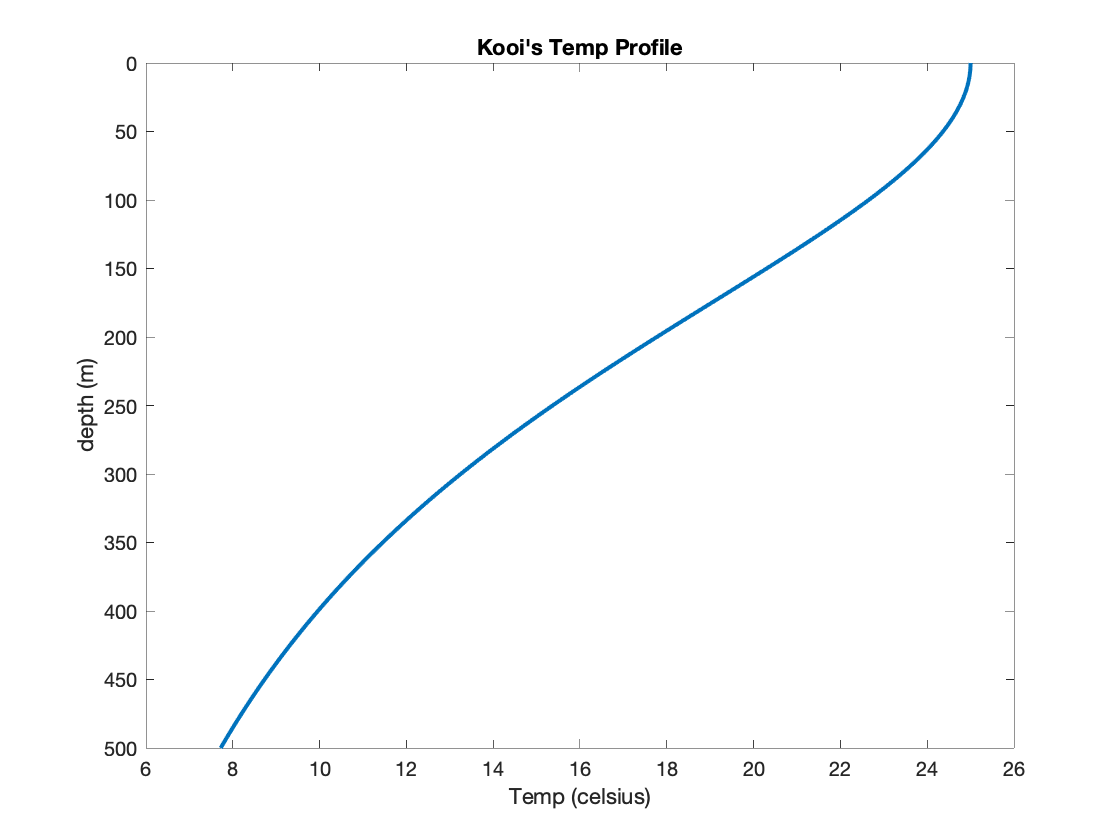

z = linspace(0, 500);
plot(T_vs_z(z), z);
set(gca, 'YDir', 'reverse');
xlabel('Temp (celsius)')
ylabel('depth (m)')
title("Kooi's Temp Profile")

Light varies a lot in the upper ocean (even in this rough profile kooi uses):

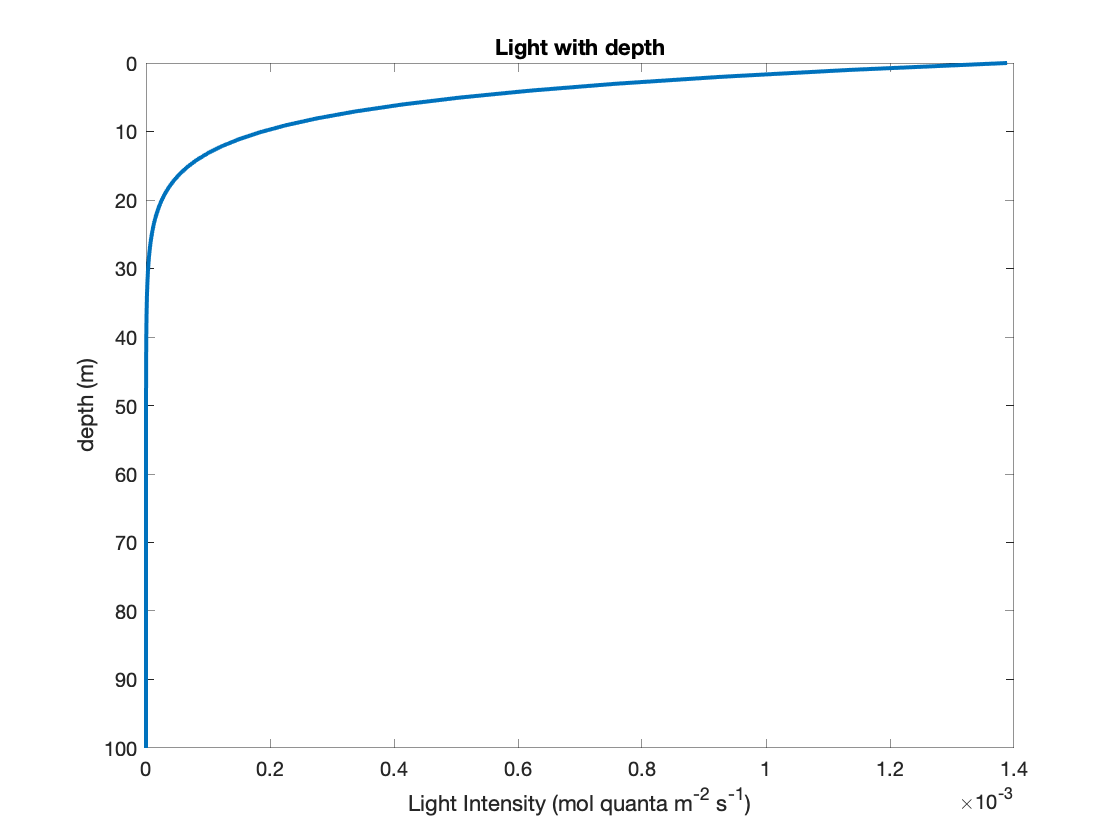

z = linspace(0, 100);
I = get_light_at_z(z, kooi_constants.I_m, kooi_constants.chl_ave_np);
figure;
plot(I, z);
set(gca, 'YDir', 'reverse');
xlabel('Light Intensity (mol quanta m^{-2} s^{-1})');
ylabel('depth (m)');
title("Light with depth");

Note: kooi's light vs depth model can't be right, it sets the euphotic depth at 25m (remember this number), which is super low.  Euphotic depth in north pacific should be like 100m.

And growth depends a lot on light:

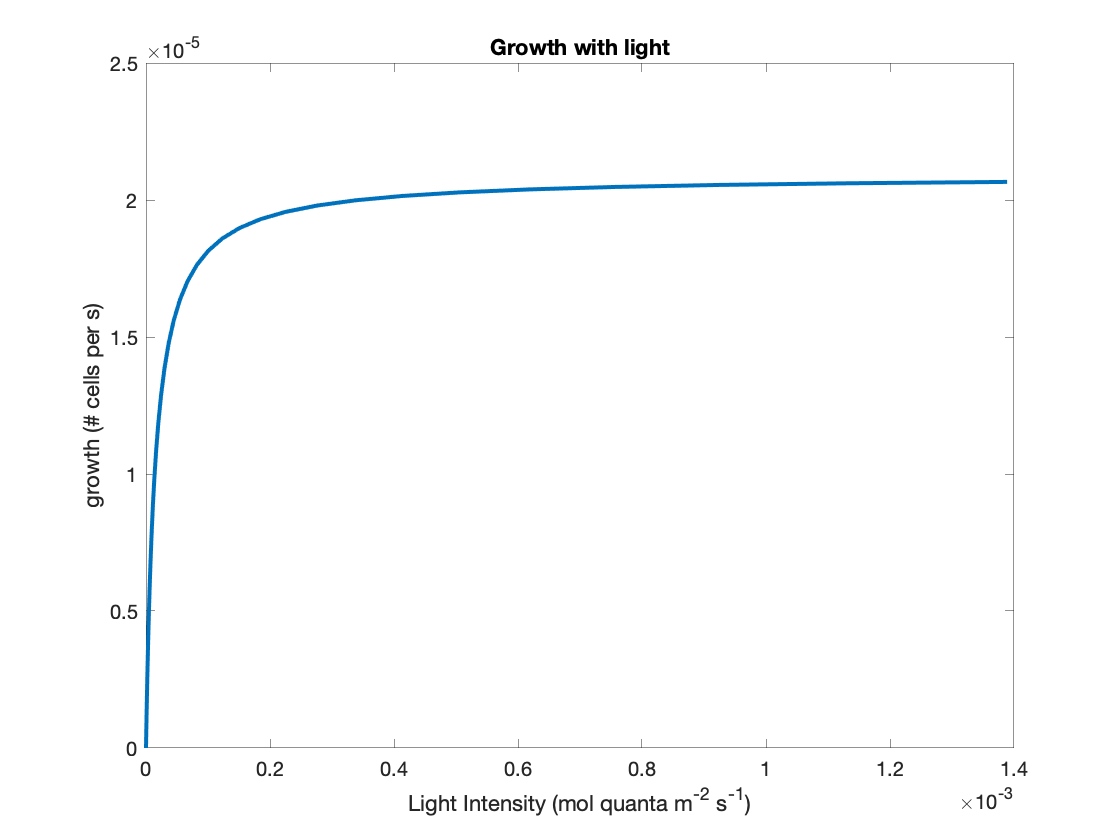

p = Particle(NaN, NaN, 1, NaN, NaN, NaN);
T = T_vs_z(z);
growth = zeros(1, 100);
for i=1:100
    growth(i) = get_algae_growth(p, T(i), I(i));
end
plot(I, growth);
xlabel('Light Intensity (mol quanta m^{-2} s^{-1})');
ylabel('growth (# cells per s)')
title("Growth with light")

Thus we can see the depth dependence of growth:

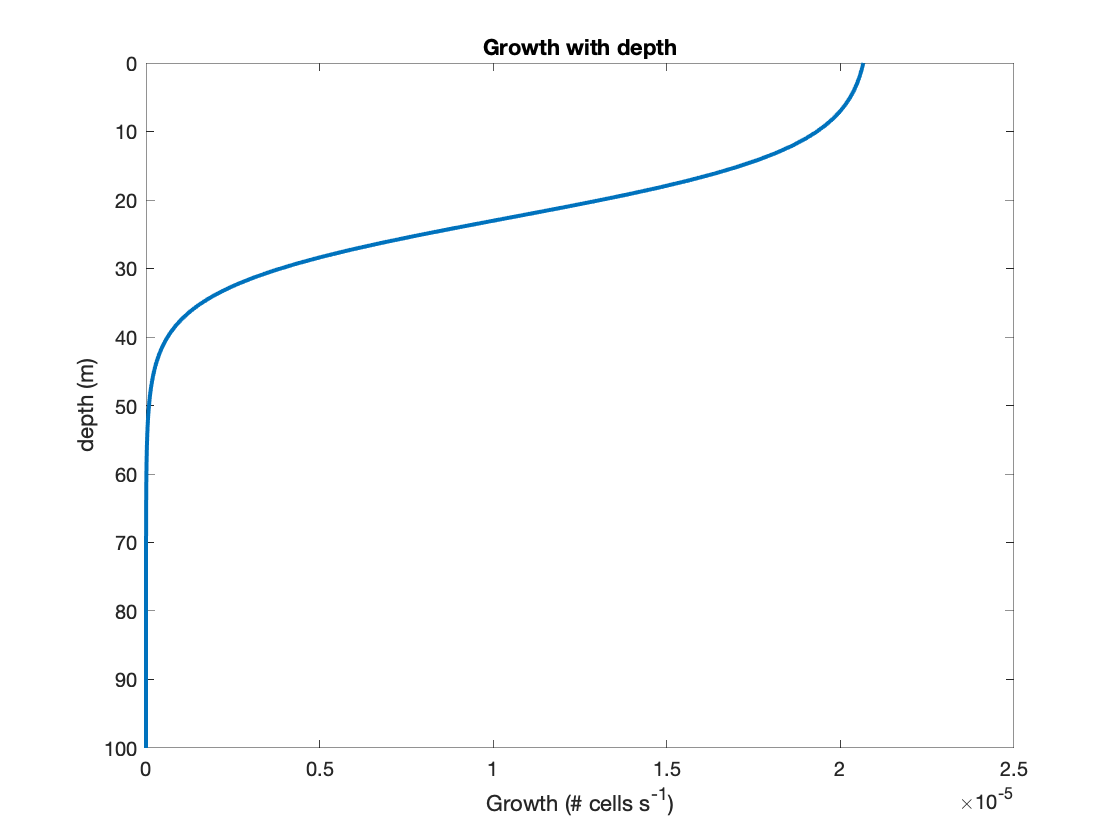

plot(growth, z);
set(gca, 'YDir', 'reverse');
xlabel('Growth (# cells s^{-1})')
ylabel('depth (m)')
title("Growth with depth")

Mortality+Respiration:

Mortality is constant, kooi sets a rate of 39% of algae per day.

Respiration depends on temperature like so:

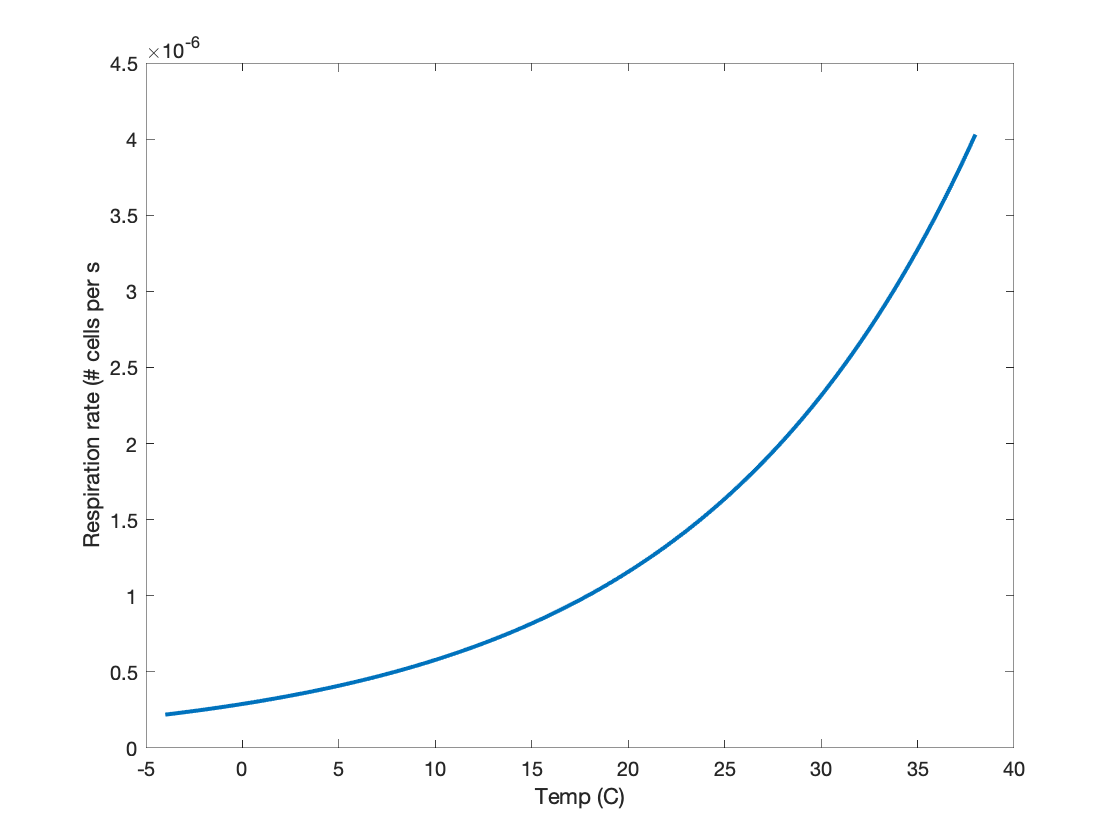

T = linspace(-4, 38, 100);
p = Particle(NaN, NaN, 1, NaN, NaN, NaN);
resp = get_algae_respiration(p, T);
figure; plot(T, resp);
xlabel('Temp (C)'); ylabel('Respiration rate (# cells per s');

T varies with depth, so again, we can do a depth analysis of "total death"

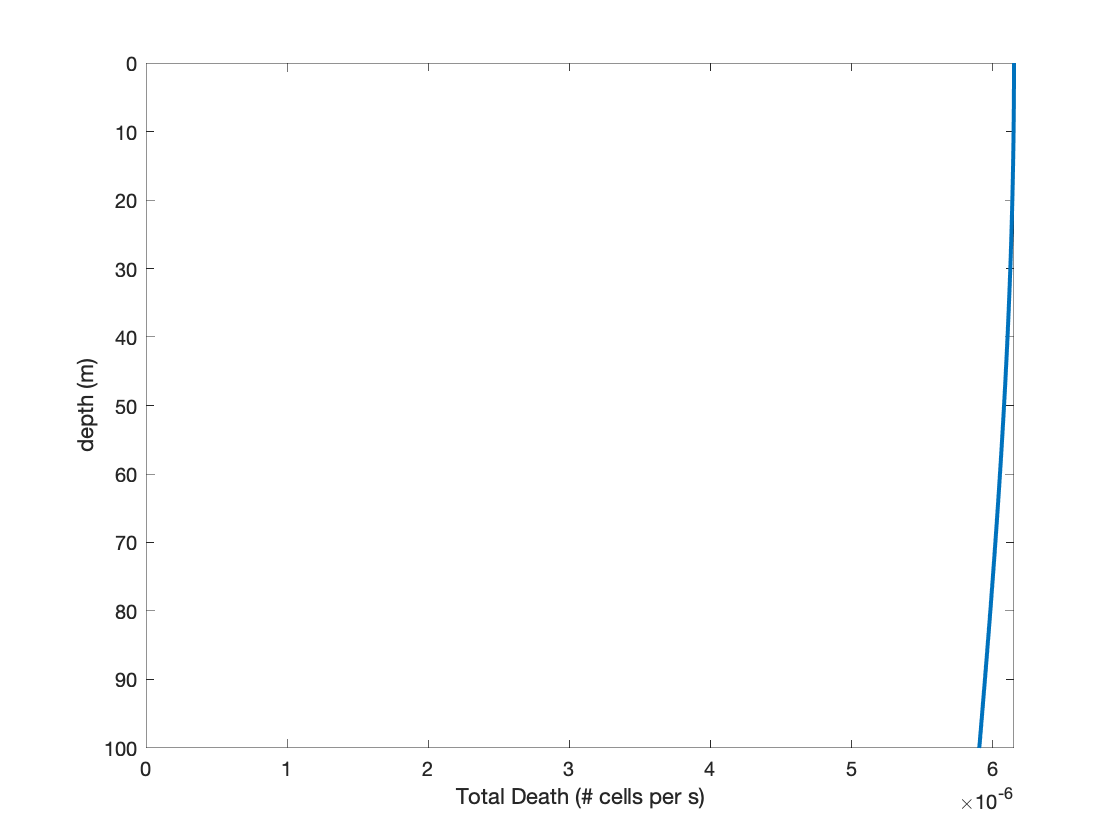

z = linspace(0, 100);
T = T_vs_z(z);
p = Particle(NaN, NaN, 1, NaN, NaN, NaN);
resp = get_algae_respiration(p, T);
mort = get_algae_mortality(p);
figure; plot(resp+mort, z);
set(gca, 'YDir', 'reverse');
xlabel('Total Death (# cells per s)');
ylabel('depth (m)')
xlim([0, max(mort+resp)]);

And so, we can combine growth and death onto the same plot to see:

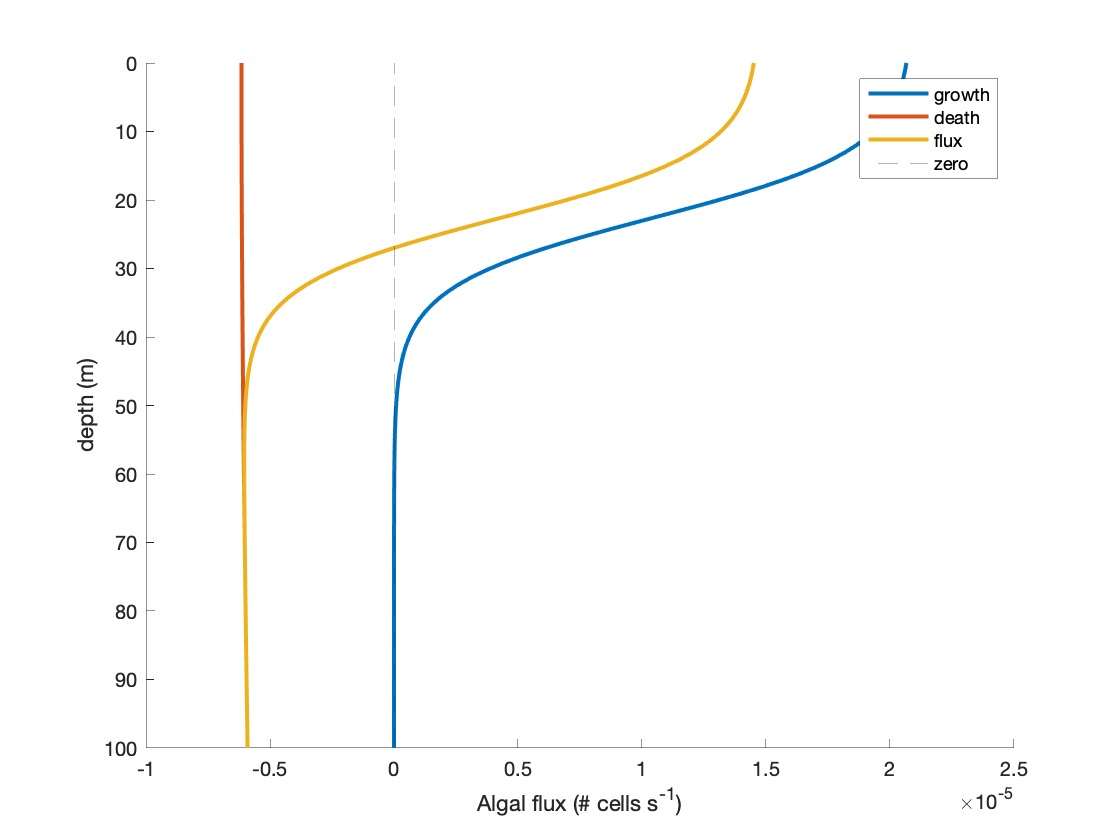

figure; hold on;
plot(growth, z, 'DisplayName', 'growth');
set(gca, 'YDir', 'reverse');
xlabel('Algal flux (# cells s^{-1})')
ylabel('depth (m)')
plot(-(resp+mort), z, 'DisplayName', 'death');
plot(growth - (resp+mort), z, 'DisplayName', 'flux');
xline(0, 'LineStyle', '--', 'DisplayName', 'zero');
legend();

Conclusions:

We can see that growth == death at ~25-30m, irrespective of particle size.  Note that this is the euphotic depth!  So we would expect particles to congregate near the euphotic depth.